# Testing april tag localization on still imgs

## Initialize ros and take care of path:

init_matlab();

path added!
Initializing global node /matlab_global_node_14924 with NodeURI http://192.168.16.78:63267/ and MasterURI http://192.168.16.71:11311/.
ROS initialization complete! :-)


## cam calibration parameters

calib_params = load("camera_calibration/calib_1024x768/cameraParams2.mat");
cam_intrinsics = calib_params.cameraParams2.Intrinsics;
cam = Camera_ROS(cam_intrinsics);

## GPS map stuff

% GPS coords of the Oval (0, 0) point
origin_latlong = [42.29322828071904, -71.26433857013662, 50];

## Load image and detect tags

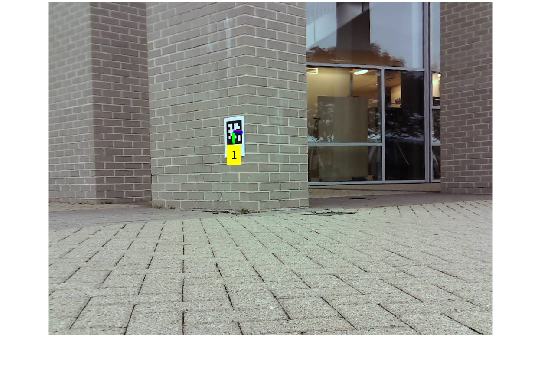

% get image from local
img = imread("block1_0.39pwm.png");

% % get image from camera
% img = rgb2gray(cam.get_image_raw());

pan_rot = Rotation2d.from_degrees(0);
[img_undistort, ~] = cam.undistort_image(img);

% run april tag detection
[num_tags, tag_ids, tag_img_corners, detected_poses] = ...
    AprilTags.detect_tags_in_image(img_undistort, cam_intrinsics);

% show img with tag overlays
img_tags_draw = AprilTags.draw_tags_on_image(img_undistort, cam_intrinsics, num_tags, tag_ids, tag_img_corners, detected_poses);
figure
imshow(img_tags_draw);

## Localize robot

% pick out first tag
tagid = tag_ids(1); tag_img_pts = tag_img_corners(:,:,1);
detected_pose = detected_poses(1);

% find robot pose from detected tag
robot_pose = AprilTags.get_robot_pose_from_localization_tag(tagid, detected_pose, tag_img_pts, pan_rot);
tag_pose = AprilTags.get_pose_of_localization_tag(tagid);

## Plot on satellite map of Oval

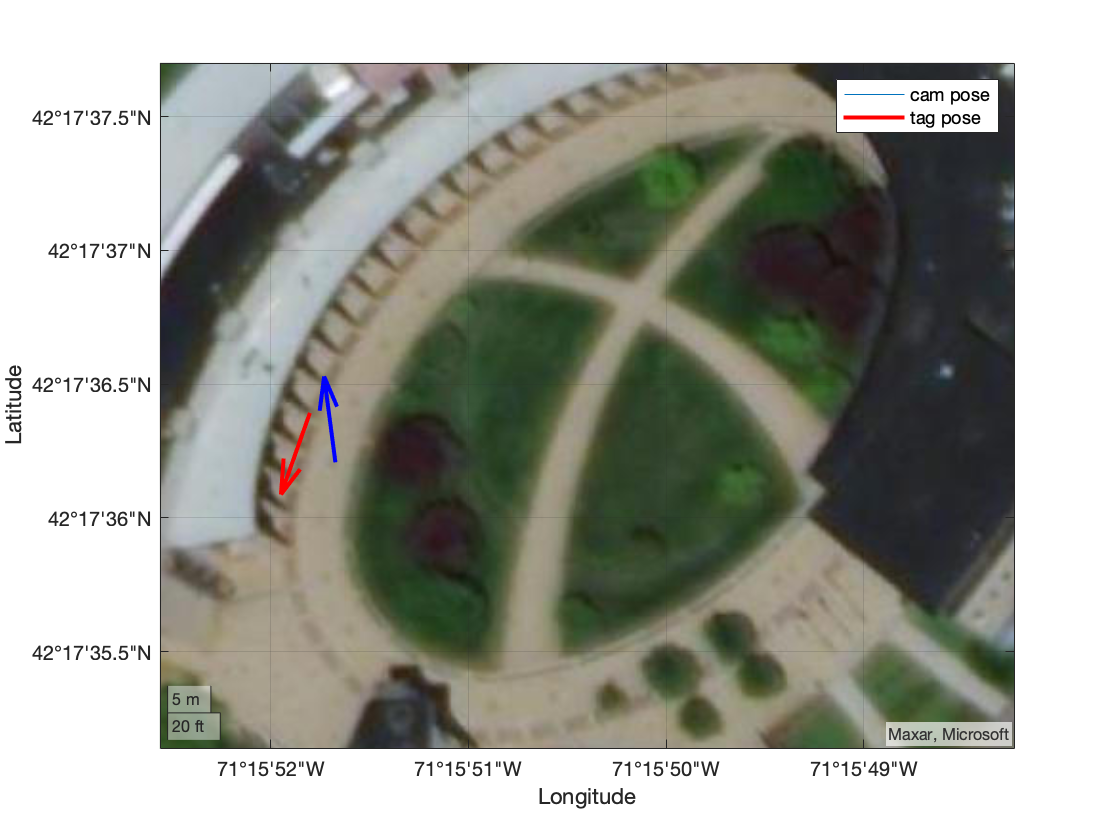

figure; hold off;
set(gcf,'Visible','on'); % pop out figure

% start geoplot
geoplot(origin_latlong(:,1),origin_latlong(:,2));

% plot poses
hold on
plot_pose_geoplot(tag_pose, origin_latlong, "r")   % plot tag pose
plot_pose_geoplot(robot_pose, origin_latlong, "b") % plot robot pose

% geoplot styling
geobasemap satellite;
% set the limits of the geoplot view
latlim = [42.2931   42.2938];
lonlim = [-71.2646  -71.2634];
geolimits(latlim, lonlim)
legend("cam pose", "tag pose")

function plot_pose_geoplot(pose, origin_latlong, linespec)
    begin_local = pose.translation;
    end_local = pose.translation.plus(...
        Translation2d(pose.rotation.vec_cos, pose.rotation.vec_sin).times(10));

    [begin_lat, begin_long,~] = ...
        local2latlon(begin_local.val_x, begin_local.val_y, 0, origin_latlong);
    [end_lat, end_long,~] = ...
        local2latlon(end_local.val_x, end_local.val_y, 0, origin_latlong);

    begin_point = [begin_lat, begin_long];
    end_point   = [end_lat,   end_long];

    plot_arrow_geoplot(begin_point, end_point, linespec)
end

function plot_arrow_geoplot(begin_point,end_point,varargin)
if ~(isvector(begin_point) && length(begin_point)==2)
   error('begin_point is not a 2D vector') 
end
if ~(isvector(end_point) && length(end_point)==2)
   error('end_point is not a 2D vector') 
end
begin_point = begin_point(:)';
end_point = end_point(:)';
pivot_x = end_point(1);
pivot_y = end_point(2);
theta = 20;
px = begin_point(1);
py = begin_point(2);
s = sind(theta);
c = cosd(theta);
px = (px - pivot_x)*0.4;
py = (py - pivot_y)*0.4;
xnew = px * c - py * s;
ynew = px * s + py * c;
px = xnew + pivot_x;
py = ynew + pivot_y;
theta = -20;
px2 = begin_point(1);
py2 = begin_point(2);
s = sind(theta);
c = cosd(theta);
px2 = (px2 - pivot_x)*0.4;
py2 = (py2 - pivot_y)*0.4;
xnew = px2 * c - py2 * s;
ynew = px2 * s + py2 * c;
px2 = xnew + pivot_x;
py2 = ynew + pivot_y;
% plot
geoplot([begin_point(1) end_point(1)],[begin_point(2) end_point(2)], varargin{:},... % line
    [px end_point(1)],[py end_point(2)],varargin{:},... % arrow end first part
    [px2 end_point(1)],[py2 end_point(2)],varargin{:},"LineWidth", 2) % arrow end second part
end

function quiver_pose(pose)
%     quiver(pose.translation.val_x, pose.translation.val_y,...
%        pose.rotation.vec_cos, pose.rotation.vec_sin, "LineWidth", 2);
%     
    pose_y = Pose2d(...
        pose.translation, pose.rotation.plus(Rotation2d.from_degrees(90)));
    quiver(pose_y.translation.val_x, pose_y.translation.val_y,...
       pose_y.rotation.vec_cos, pose_y.rotation.vec_sin, "LineWidth", 2);
end

function plot_pose_oval(robot_pose, tag_id)
    oval_img = imread("test_data/oval_satellite.png");
    imshow(oval_img)
end